## **Polynomiální regrese:**

Funkce má za úkol nalézt polynomiální aproximaci na základně naměřených tréninkových dat $\mathit{\mathbf{t}}$ pro dané body $\mathit{\mathbf{x}}$**,** a požadovaného řádu polynomu $M$. Funkce také dokáže provést případnou regularizací $\lambda$. Jako výstup z funkce jsou vzorky aproximace $t_{\left(w\right)}$ pro tréninkové body $\mathit{\mathbf{x}}$, dále koeficienty aproximačního polynomu $\mathit{\mathbf{w}}$, rozdíl aproximační křivky od tréninkových dat $\mathit{\mathbf{e}}$, a nakonec chybu vyjádřenou metodou nejmenších čtverců.

Jak na polynomiální regresi? Na začátku vycházíme ze vzorečku níže:

#### 
$$t_{\left(w,x\right)} =w_0 +w_1 x+w_2 x^2 +w_3 x^3 \ldotp \ldotp \ldotp +w_M x^M$$


kde $t$ je výstupní hodnota v určitém bodě $x$. $w_m$ jsou zase koeficienty aproximačního polynomu, kde $M$je řád polynomu. Jinak zapsáno:

#### 
$$t_{\left(w,x\right)} =\sum_{m\;=\;0}^M w_m \;x^m$$


Pokud bychom nechtěli přímo polynomiální regresi, ale kteroukoliv jinou obecně. Můžeme místo vyjádření polynomiální regrese psát obecnou tzv. bázovou funkci $\varphi$. Vzorec by potom vypadal:

#### 
$$t_{\left(w,x\right)} =\sum_{m\;=0}^M w_m \;\varphi_{m\left(x\right)}$$
      

kde tedy pro polynomiální regresi platí: $\;\varphi_{m\left(x\right)} =x^m$. 

Výraz $t_{\left(w,x\right)}$ výše je možné přepsat maticově do podoby:

#### 
$$t_{\left(w,x\right)} =W\phi_{\left(x\right)}$$
                
$$\left\lbrack N\times 1\right\rbrack =\left\lbrack N\times M\right\rbrack \left\lbrack M\times 1\right\rbrack$$


kde $\phi_{\left(\mathit{\mathbf{x}}\right)}$ je matice vyjadřující všechny bázové funkce. Pro polynomiální regresi bázová matice vypadá takto:

#### 
$$\phi_{\left(\mathit{\mathbf{x}}\right)} =\left\lbrack \begin{array}{ccccc}
1 & x_1  & {x_1 }^2  & \cdots  & {x_1 }^M \\
1 & x_2  & {x_2 }^2  & \cdots  & {x_2 }^M \\
1 & x_3  & {x_3 }^2  & \cdots  & {x_3 }^M \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_N  & {x_N }^2  & \cdots  & {x_N }^M 
\end{array}\right\rbrack$$


kde **M** odpovídá řádu aproximačního polynomu a **N** zase počtu vstupních (tréninkových) hodnot. Matice koeficientů polynomu ${\mathit{\mathbf{W}}}^{\mathit{\mathbf{T}}}$ a matice výstupních hodnot ${\mathit{\mathbf{t}}}_{\left(\mathit{\mathbf{w}},\mathit{\mathbf{x}}\right)}$ má potom podobu:

#### 
$${\mathit{\mathbf{t}}}_{\left(\mathit{\mathbf{w}},\mathit{\mathbf{x}}\right)} \;=\left\lbrack \begin{array}{c}
t_1 \\
t_2 \\
t_3 \\
\vdots \\
t_N 
\end{array}\right\rbrack$$
            
$$W\;=\left\lbrack \begin{array}{c}
w_1 \\
w_2 \\
w_3 \\
\vdots \\
w_N 
\end{array}\right\rbrack$$
     

Čili maticovou rovnici lze rozepsat takto:   

#### 
$$t_{\left(w,x\right)} =W\phi_{\left(x\right)} =\left\lbrack \begin{array}{c}
t_1 \\
t_2 \\
t_3 \\
\vdots \\
t_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & x_1  & {x_1 }^2  & \cdots  & {x_1 }^M \\
1 & x_2  & {x_2 }^2  & \cdots  & {x_2 }^M \\
1 & x_3  & {x_3 }^2  & \cdots  & {x_3 }^M \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_N  & {x_N }^2  & \cdots  & {x_N }^M 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1 \\
w_2 \\
w_3 \\
\vdots \\
w_N 
\end{array}\right\rbrack \;$$
        
$$\left\lbrack N\times 1\right\rbrack =\left\lbrack N\times M\right\rbrack \left\lbrack M\times 1\right\rbrack$$


Je důležité si uvědomit, že bázové funkce mohou mít i naprosto olišnou podobu, nejenom polynomiální. 

Nyní můžeme spočítat v MATLABu soustavu rovnic pomocí vzorce:

#### 
$$W=\phi_{\left(x\right)} \backslash t_{\left(w,x\right)}$$


 a dostat tak všechny koeficienty. My si to ale chceme spočítat poctivě celé, takže metoda nejmenších čtverců principiálně:

#### 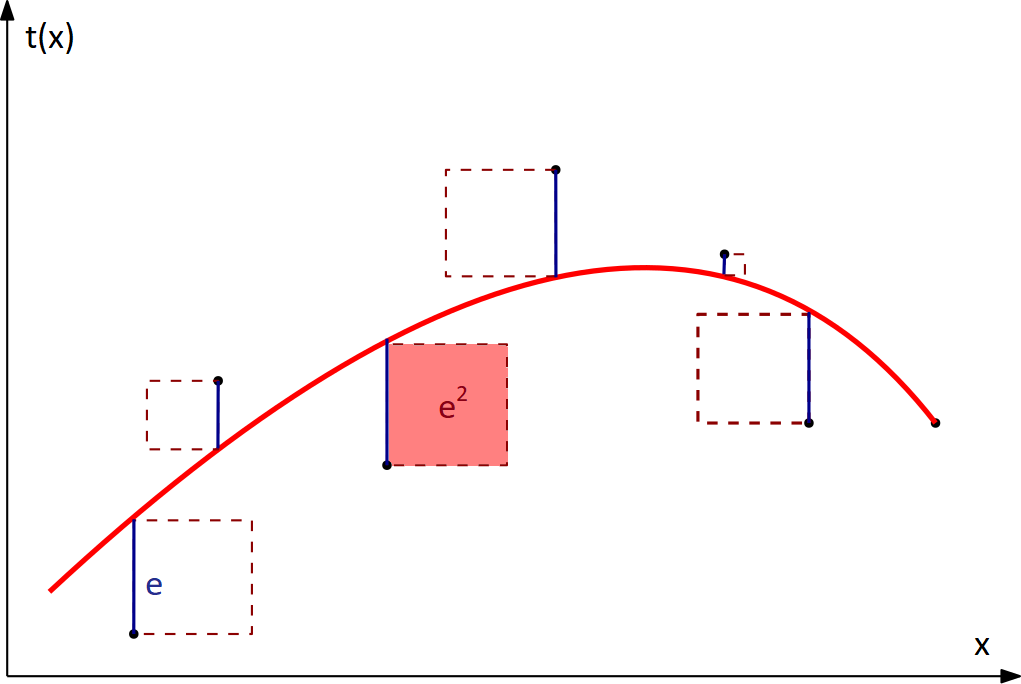

Na ose $y$ jsou naměřřené tréninkové hodnoty $\mathit{\mathbf{t}}$ v závislosti na vstupní veličině $x$. Černé tečky odpovídají naměřeným tréninkovým hodnotám $\mathit{\mathbf{t}}$, a červená křivka odpovídá aproximačnímu proložení těchto bodů. Odchylky aproximace od tréninkových dat jsou naznačeny písmenem $\mathit{\mathbf{e}}$ a jedná se vlastně o rozdíl naměřených dat a dat aproximačních. V metodě nejmenších čtverců nepracujeme s hodnotami odchylek, ale s hodnotami jejich druhých mocnin, jak naznačují v obrázku čtverce. Cílem metody nejmenších čtverců je nalést takovou aproximaci, která má součet ploch těchto čtverců co možná nejmenší.   

vyjádříme si tedy maticově odchyklu aproximačních dat od tréninkových dat:

#### 
$$E=W\phi_{\left(x\right)} -\;t_{\left(w,x\right)} =\left\lbrack \begin{array}{c}
e_1 \\
e_2 \\
e_3 \\
\vdots \\
e_N 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & x_1  & {x_1 }^2  & \cdots  & {x_1 }^M \\
1 & x_2  & {x_2 }^2  & \cdots  & {x_2 }^M \\
1 & x_3  & {x_3 }^2  & \cdots  & {x_3 }^M \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_N  & {x_N }^2  & \cdots  & {x_N }^M 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_1 \\
w_2 \\
w_3 \\
\vdots \\
w_N 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
t_1 \\
t_2 \\
t_3 \\
\vdots \\
t_N 
\end{array}\right\rbrack$$


Nyní aplikujeme metodu nejmenších čtverců, čili provedeme sumu druhých mocnin odchylek $E$. Maticově takovou sumu můžeme získat jako vynásobení matice E sama sebou, ale transponovanou.   

#### 
$$E^T E=$$
 
$$\left\lbrack \begin{array}{ccccc}
e_1  & e_2  & e_3  & \cdots  & e_N 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
e_1 \\
e_2 \\
e_3 \\
\vdots \\
e_N 
\end{array}\right\rbrack$$


Pokud hledáme minimální součet čtverců, hledáme vlastně minimum funkce výše, tj. $E^T E$. Pokud hledáme minimum této funkce, je potřeba nalézt gradient, čili parciální derivaci podle všech koeficientů $W$. Před provedením parcíálních derivací provedeme ještě matematickou úpravu vztahu výše:

#### 
$$E^T E={\left(W\phi_{\left(x\right)} -\;t_{\left(w,x\right)} \right)}^T \left(W\phi_{\left(x\right)} -\;t_{\left(w,x\right)} \right)=\left({\phi_{\left(x\right)} }^T W^T -{t_{\left(w,x\right)} }^T \right)\left(W\phi_{\left(x\right)} -\;t_{\left(w,x\right)} \right)$$


####           
$$\begin{array}{l}
=\left({\phi_{\left(x\right)} }^T W^T W\phi_{\left(x\right)} \right)-\left({\phi_{\left(x\right)} }^T W^T t_{\left(w,x\right)} \right)-\left({t_{\left(w,x\right)} }^T W\phi_{\left(x\right)} \right)+\left({t_{\left(w,x\right)} }^T t_{\left(w,x\right)} \right)\\
=\left({\phi_{\left(x\right)} }^T W^T W\phi_{\left(x\right)} \right)-\left(2{\phi_{\left(x\right)} }^T W^T t_{\left(w,x\right)} \right)+\left({t_{\left(w,x\right)} }^T t_{\left(w,x\right)} \right)
\end{array}$$


A poté derivace vztahu výše se musí rovnat nule (hledání lokálního minima funkce):

#### 
$$\frac{\partial }{\partial W}E^T E=$$

$$2{\phi_{\left(x\right)} }^T \phi_{\left(x\right)} W-2{\phi_{\left(x\right)} }^T t_{\left(w,x\right)} =0$$


Už pouze finální úprava s vydělením dvojkou a přeházení členů:

#### 
$${\phi_{\left(x\right)} }^T \phi_{\left(x\right)} W\;={\phi_{\left(x\right)} }^T t_{\left(w,x\right)}$$


A z toho vyplívá:

### 
$$\mathit{\mathbf{W}}={\left({\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} \phi_{\left(\mathit{\mathbf{x}}\right)} \right)}^{-1} -{\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} {\mathit{\mathbf{t}}}_{\left(\mathit{\mathbf{w}},\mathit{\mathbf{x}}\right)}$$


Tohle bylo prostě ono odvození metody nejmenších čtverců.

Nakonec se sluší říct, že funkce je schopna provádět tzv. regularizaci, tj. utlumení vysokých koeficientů $\mathit{\mathbf{w}}$ aproximačního polynomu. Tím se vzorec upraví o tlumící člen $\lambda I$:

#### 
$$\mathit{\mathbf{W}}={\left({{\lambda I+\;\phi }_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} \phi_{\left(\mathit{\mathbf{x}}\right)} \right)}^{-1} -{\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} {\mathit{\mathbf{t}}}_{\left(\mathit{\mathbf{w}},\mathit{\mathbf{x}}\right)}$$


kde $I$ je jednotková matice a $\lambda$ odpovídá míře utlumení.

Nyní už to jen narvat do kódu:

function [t_w,w,e,E_w] = Polynomial_regression(x,t,M,lambda) 
%   x:          vzorkovací čas
%   t:          naměřenné vzorky
%   M:          řád polynomu
%   lambda:     regularizační člen
%   t_w:        body aproximace pro vstupní hodnoty x
%   w:          koeficienty aproximačního polynomu
%   e:          rozdíl bodů aproximační funkce a naměřených výstupů
%   E_w:        velikost druhých mocnin rozdílů e (metoda nejmenších čtverců)

N = length(x);          % počet pozorování získaný z délky vektoru vstupních hodnot
t = t';                 % s maticí výstupů chci pracovat jako se sloupcovým vektorem

Nejprve je připravena bázová matice $\phi_{\left(x\right)}$.

Phi = zeros(N,M+1);
for j = 0:M
    for i = 0:N-1
        Phi(i+1,j+1) = x(i+1)^j;
    end
end

% w = Phi\t; % MATLAB by dokázal vyřešit i tuhle soustavu rovnic, ale my si to dáme hezky poctivě přes následující vzoreček:

Následně jsou připraveny také matice pro výpočet dle vzorečku $\mathit{\mathbf{W}}={\left({\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} \phi_{\left(\mathit{\mathbf{x}}\right)} \right)}^{-1} -{\phi_{\left(\mathit{\mathbf{x}}\right)} }^{\mathit{\mathbf{T}}} {\mathit{\mathbf{t}}}_{\left(\mathit{\mathbf{w}},\mathit{\mathbf{x}}\right)}$**.**

Phi_T_x_Phi = Phi'*Phi;
Phi_T_x_t = Phi'*t;

Za povšimnutí zde stojí právě regularizační člen $\lambda I$, v kódu proveden příkazem "lambda *eye()"

w = ((((lambda.*eye(M+1))+Phi_T_x_Phi)^(-1))*Phi_T_x_t);    % koeficienty vypočeteného polynomu

V dalším kroku jsou spočteny hodnoty aproximace pro vektor vstupů $\mathit{\mathbf{x}}$.

t_w = Polynomial_evaluation(x,w);

Následuje metoda nejmenších čtverců, do níž jsou zadány jako vstupní argumenty zadány testovací hodnoty původní funkce a také hodnoty aproximace. Hodnota nejmenších čtverců v podstatě jen spočítá odchylky aproximace od původních dat a vytvoří z nich kvadrát. 

[E_w,e] = Least_squares_method(t',t_w);

end